# Time-dependent variational principle (TDVP): 2-site variant

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

Here we will implement the 2-site TDVP method for simulating the real-time evolution of one-dimensional quantum states.

## Exercise (a): Complete the function for 2-site TDVP

There is a function `TDVP_2site_Ex.m`, which is in the same sub-directory with this script. It is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

The detailed algorithm of the 2-site TDVP is described in described in Appendix C of Haegeman2016 [[J. Haegeman, C. Lubich, I. Oseledets, B. Vandereycken, and F. Verstraete, Phys. Rev. B **94**, 165116 (2016)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.94.165116)] or Sec. 6.2 of Paeckel2019 [[S. Paeckel, T. Köhler, A. Swoboda, S. R. Manmana, U. Schollwöck, and C. Hubig, Ann. Phys. **411**, 167998 (2019)](https://www.sciencedirect.com/science/article/pii/S0003491619302532?via%3Dihub)].

You can adopt many parts of the 2-site TDVP code from the 1-site TDVP code (`DMRG/TDVP_1site.m`) and the 2-site DMRG code (`DMRG/DMRG_GS_2site.m`).

Let's compare the accuracy of the 2-site TDVP with the 1-site variant. For this, we again consider the example of the domain wall dynamics in the XY chain.

clear

% system parameter
J = -1; % coupling strength
L = 40; % number of sites in a chain

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(4,4);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = S(:,:,1);
Hloc{3,1} = S(:,:,3);
Hloc{4,2} = J*S(:,:,1)';
Hloc{4,3} = J*S(:,:,3)';
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

% TDVP parameters
Nkeep = 20; % bond dimension
dt = 1/20; % discrete time step size
tmax = 15; % maximum time

% operator to measure magnetization
Sz = S(:,:,2);

Let's first run the 1-site TDVP calculation. Note that we need to declare large tensors since the 1-site method cannot increase bond dimensions. Also, since the bond spaces of separable states can be chosen wrongly, we need to assign small elements as a "trick."

M0 = cell(1,L);
v = [1,1e-8]; v = v/norm(v);
for itN = (1:L)
    if itN == 1
        M0{itN} = zeros(1,Nkeep,size(I,2));
    elseif itN == L
        M0{itN} = zeros(Nkeep,1,size(I,2));
    else
        M0{itN} = zeros(Nkeep,Nkeep,size(I,2));
    end

    if itN <= (L/2)
        M0{itN}(1,1,:) = reshape(v,[1 1 2]);
    else
        M0{itN}(1,1,:) = reshape(fliplr(v),[1 1 2]);
    end
end

[ts,~,Ovals1] = TDVP_1site (M0,Hs,Sz,Nkeep,dt,tmax);

TDVP : Real-time evolution with local measurements
N = 40, Nkeep = 20, dt = 0.05, tmax = 15 (300 steps)
22-11-04 16:33:35 | Time evolution: start.
22-11-04 16:33:55 | #30/300 : t = 1.5/15
22-11-04 16:34:15 | #60/300 : t = 3/15
22-11-04 16:34:35 | #90/300 : t = 4.5/15
22-11-04 16:34:55 | #120/300 : t = 6/15
22-11-04 16:35:15 | #150/300 : t = 7.5/15
22-11-04 16:35:34 | #180/300 : t = 9/15
22-11-04 16:35:55 | #210/300 : t = 10.5/15
22-11-04 16:36:19 | #240/300 : t = 12/15
22-11-04 16:36:43 | #270/300 : t = 13.5/15
22-11-04 16:37:02 | #300/300 : t = 15/15
Elapsed time: 207.8s, CPU time: 1533s, Avg # of cores: 7.379
22-11-04 16:37:02 | Memory usage : 2.52GiB


Then we run the 2-site TDVP. For this 2-site update method, we can use the compact form of the initial state without extra tricks.

M0 = cell(1,L);
for itN = (1:L)
    if itN <= (L/2)
        M0{itN} = permute([1 0],[1 3 2]);
    else
        M0{itN} = permute([0 1],[1 3 2]);
    end
end

[~,~,Ovals2] = TDVP_2site_Ex (M0,Hs,Sz,Nkeep,dt,tmax);

2-site TDVP : Real-time evolution with local measurements
N = 40, Nkeep = 20, dt = 0.05, tmax = 15 (300 steps)
22-11-04 16:37:03 | Time evolution: start.
22-11-04 16:37:12 | #30/300 : t = 1.5/15
22-11-04 16:37:24 | #60/300 : t = 3/15
22-11-04 16:37:39 | #90/300 : t = 4.5/15
22-11-04 16:37:58 | #120/300 : t = 6/15
22-11-04 16:38:21 | #150/300 : t = 7.5/15
22-11-04 16:38:47 | #180/300 : t = 9/15
22-11-04 16:39:12 | #210/300 : t = 10.5/15
22-11-04 16:39:40 | #240/300 : t = 12/15
22-11-04 16:40:07 | #270/300 : t = 13.5/15
22-11-04 16:40:31 | #300/300 : t = 15/15
Elapsed time: 208.5s, CPU time: 1101s, Avg # of cores: 5.28
22-11-04 16:40:31 | Memory usage : 2.56GiB


Let's plot the errors.

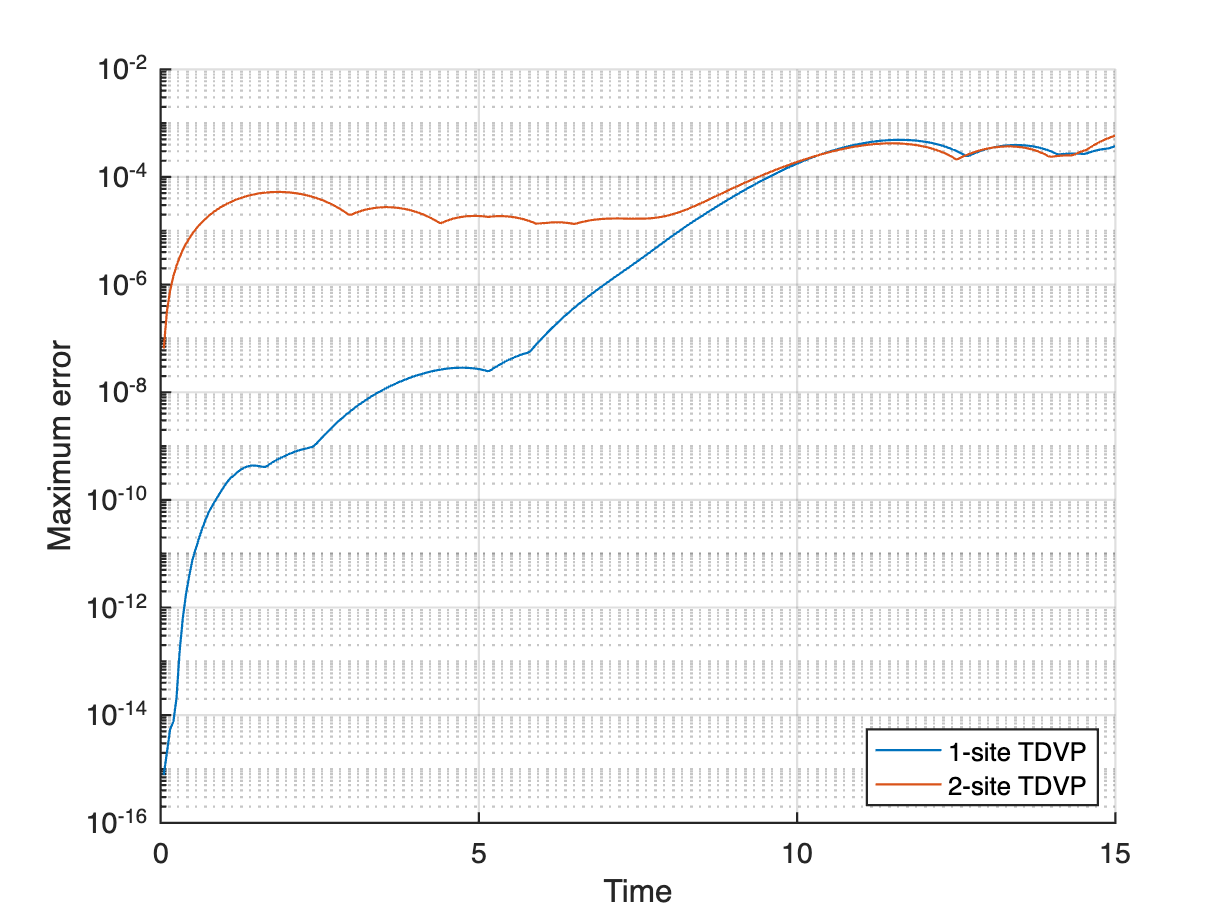

% exact values of magnetization in the infinite chain limit
fvals = zeros(numel(ts),L-1);
for it = (1:size(fvals,2))
    % Bessel function of the 1st kind
    fvals(:,it) = (besselj(it-(L/2),ts(:))).^2;
end
fvals = -0.5*fvals;

Oexact = zeros(numel(ts),L/2); % exact values
for it = (1:(L/2))
    Oexact(:,it) = sum(fvals(:,(L/2-it+1):(it+L/2-1)),2);
end
Oexact = [-fliplr(Oexact),Oexact];

% error between numerical and exact results
figure;
hold on;
% maximum error along the chain at each time instance
plot(ts,max(abs(Ovals1-Oexact),[],2),'LineWidth',1);
plot(ts,max(abs(Ovals2-Oexact),[],2),'LineWidth',1);
hold off
set(gca,'FontSize',13,'LineWidth',1,'YScale','log');
grid on;
xlabel('Time');
ylabel('Maximum error');
legend({'1-site TDVP','2-site TDVP'},'Location','southeast');

Surprisingly, the 2-site TDVP has a larger error at earlier times before the runaway time (after which the finite bond dimensions cannot fully capture the large entanglement generated along the time evolution). This larger error is because that the subspace projected by the global 2-site projector, used in the 2-site TDVP, does not only contain the tangent space. So it reveals the fact that the 2-site TDVP is not mathematically "clean" as the 1-site TDVP.

However, this error is relatively minor, compared to the major sources such as the projection error. In this example, such minor error is visible since the target state is rather simple; the left-most and right-most parts of the states are almost separable, until they meet the wavefront of the magnetization fluctuation. So the strength of the 2-site method (i.e., the on-the-fly exploration of the bond spaces) does only show up in shorter CPU time spent; the 2-site method takes smaller bond dimensions if they are enough to capture the entanglement. Moreover, our 1-site TDVP calculations could be stabilized by using some tricks in initializing the state; without those tricks, the 1-site TDVP may fail. (**Quick exercise:** Try out!)